## fv0 Intro

This scrip import expomential fitness as experiment data, and simulation result comes from GLE model with potential=0.5*psi*x^2

This scrip just changing para by hand and make the frame of simulation.

## GLENII fv0 Intro

change FDE into GLENII

## Import data and previewing

The data come from expomential fitness data.

data_name='p179';
selecting_curve='xy';

data_mode="mixed data";%data mode is "processed data" or "mixed data"
Selecting_Mode='discard'; %'discard','average'
if data_mode=="processed data"
    experiment_interval=30;
    min_length=40;
    time_scale=experiment_interval*(1:min_length);
    
    load(['C:\Users\zhouquan\OneDrive\research\scrips\processed_data\processed data ',data_name,'_',num2str(experiment_interval),'s.mat'])
    
    fun=inline('a(1)*exp(a(2)*t)+a(3)*exp(a(4)*t)','a','t');
    t=time_scale;
    a(1)=2.542e+05;%n142_30s
    a(2)=9.705e-05;
    a(3)=-1.391e+05;
    a(4)=-0.01086;
    
    Reserved_length=min_length;
    interceptive_experiment_MSD=[time_scale;1e-18*fun(a,time_scale)];
elseif data_mode=="mixed data"
    interceptive_experiment_MSD=[];
    load(['C:\Users\zhouquan\OneDrive\research\scrips\processed_data\mixed data ',data_name,' ', Selecting_Mode,'.mat'])
    for i=1:length(t_mixMSD(1,:))
        if t_mixMSD(1,i)<=1200
            interceptive_experiment_MSD=[interceptive_experiment_MSD,[t_mixMSD(1,i);1e-18*t_mixMSD(2,i)]];
        end
    end
end

## Parameter importing

kB=1.3806505e-23;
T=293;%confirmed

GLE_input=[1.9227e-08,	7.014e-07,	0.6107];

%m=GLE_input(1);
%psi=GLE_input(2);
mpsi=GLE_input(1);
zeta=GLE_input(2);
H=GLE_input(3);

## Main loop

simulation_MSD=[];
tau=((zeta*gamma(2*H+1))/mpsi)^(1/(2-2*H));
for t=interceptive_experiment_MSD(1,:)
    simulation_MSD=[simulation_MSD,2*kB*T/mpsi-2*kB*T/mpsi*mlf(2-2*H,1,-(t/tau)^(2-2*H),8)];
end
residual=sum((interceptive_experiment_MSD(2,:)-simulation_MSD).^2);

## Plot and saving

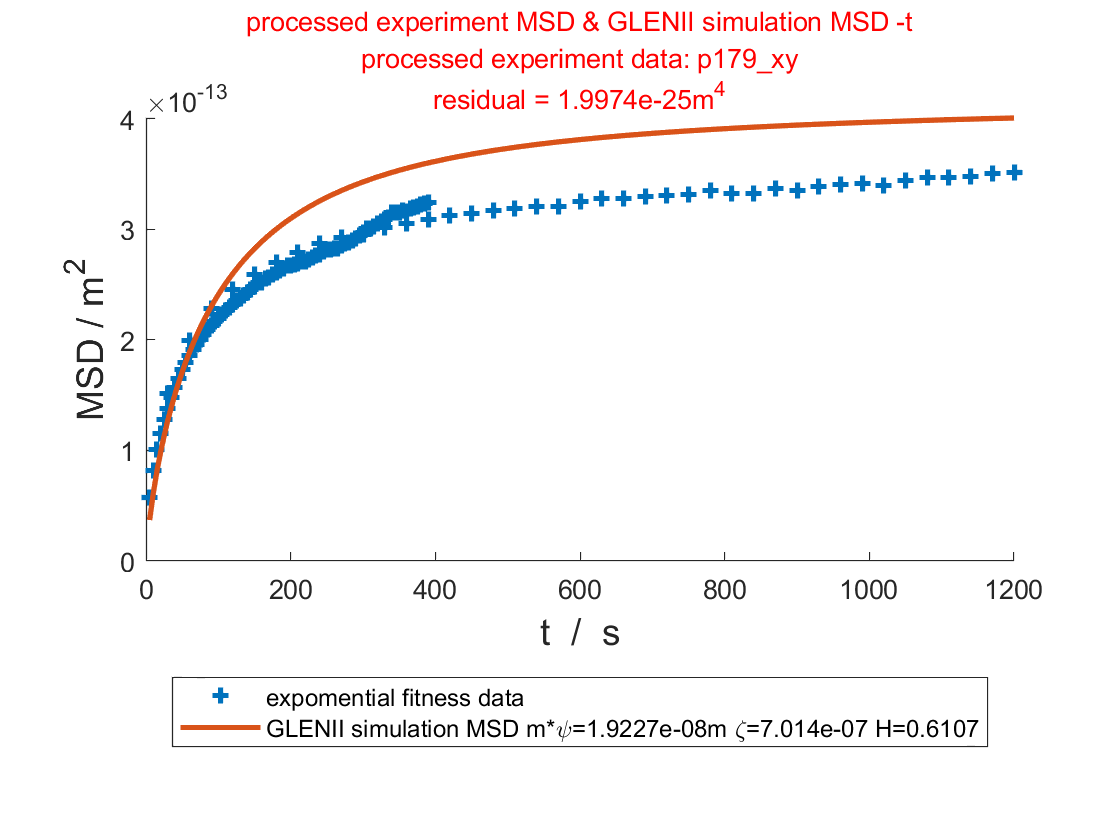

figure
hold on
plot(interceptive_experiment_MSD(1,:),interceptive_experiment_MSD(2,:),'+',"LineWidth",2,'displayname','expomential fitness data')
%plot(time_scale,1e-18*processed_MSD(1:min_length),'+',"DisplayName",'experiment xy average data',"Color",'cyan',"LineWidth",1)
legend_name=strcat('GLENII simulation MSD',' m*\psi= ',num2str(mpsi),'m \zeta=',num2str(zeta),' H= ',num2str(H));
plot(sort(interceptive_experiment_MSD(1,:)),sort(simulation_MSD),"LineWidth",2,'displayname',legend_name)
xlabel('t  /  s','FontSize',14);
ylabel('MSD / m^2','FontSize',14);
title({['processed experiment MSD & GLENII simulation MSD -t'],['processed experiment data: ',strrep(data_name,'_','\_'),'\_',selecting_curve],['residual = ',num2str(residual),'m^4']},'Color','r','FontSize',10);
legend('Location','southoutside');

## Saving

storage_location='C:\Users\zhouquan\OneDrive\research\DNA随机游走模拟\阶段报告2022.04图像';
c=clock;
%saveas(gcf,strrep([storage_location,'\image\GLE-MSD ',data_name,'_',num2str(experiment_interval),'s ',num2str(c(1)),'.',num2str(c(2)),'.',num2str(c(3)),' ',num2str(c(4)),num2str(c(5)),'.jpg'],'       ',' '))
